%--------------------------
clear all;
cd('C:\Users\xy123\Matlab\Nlab_matlab/exp3_analysis/');

%-----------------------------------
% Acitivate at exp3_analysis
resultpath = "./results/";
ana_result = "analysis/";
Datapath = "./data/";

MatNames1 = {'cu0025', 'cu0129', 'pla0075', 'pla0225'};
MatNames2 = {'cu_0.025', 'cu_0.129', 'pla_0.075', 'pla_0.225'};
MatNames3 = {'cu-0.025', 'cu-0.129', 'pla-0.075', 'pla-0.225'};
HDRNames_15 = [19, 39, 78, 80, 102, 125, 152, 203, 226, 227, 230, 232, 243, 278, 281];
HDRNames_30 = [5,19,34,39,42,43,78,80,102,105,125,152,164,183,198,201,202,203,209,222,226,227,230,232,243,259,272,278,281,282];
HDRNum_15 = [2,4,7,8,9,11,12,18,21,22,23,24,25,28,29];
HDRNum_30 = [1,2,3,4,5,6,7,8,9,10,11,12,13,14,15,16,17,18,19,20,21,22,23,24,25,26,27,28,29,30];
ShapeNames = {'sphere','bunny','dragon','boardA','boardB','boardC'};

% load data
load(strcat(Datapath,'Exp1Mi_data.mat'));
load(strcat(Datapath,'Exp2Mi_data.mat'));
load(strcat(Datapath,'Exp1Th_data.mat'));
load(strcat(Datapath,'Exp2Th_data.mat'));
load(strcat(Datapath,'Exp3_data.mat'));
load(strcat(Datapath,'Inoue_data.mat'));
load(strcat(Datapath,'lummodel_data.mat'));
load(strcat(Datapath,'objmodel_data.mat'));

%変数
%{
Exp3HMSPT = Exp3RowHMSPT;
Exp3HMS = Exp3NormHMS;
Exp3HS = Exp3NormHS;
Exp3HM = Exp3NormHM;
Exp3H = Exp3NormH;
Exp3HM15 = Exp3Zs15bnyHM;
Exp3H15 = Exp3Zs15bnyH;
err_Exp3HMS = error_Exp3NormHMS;
err_Exp3HM = error_Exp3NormHM;
err_Exp3HS = error_Exp3NormHS;
err_Exp3H = error_Exp3NormH;
err_Exp3HM15 = error_Exp3HM15;
err_Exp3H15 = error_Exp3H15;
%}


Exp3HMSPT = Exp3RowHMSPT;
Exp3HMS = Exp3ZsHMS;
Exp3HS = Exp3ZsHS;
Exp3HM = Exp3ZsHM;
Exp3H = Exp3ZsH;
Exp3HM15 = Exp3Zs15bnyHM;
Exp3H15 = Exp3Zs15bnyH;
err_Exp3HMS = error_Exp3ZsHMS;
err_Exp3HM = error_Exp3ZsHM;
err_Exp3HS = error_Exp3ZsHS;
err_Exp3H = error_Exp3ZsH;
err_Exp3HM15 = error_Exp3HM15;
err_Exp3H15 = error_Exp3H15;


LumModelH = lummodelH;
Error_LumModelH = zeros(size(LumModelH));
LumModelNormH = lummodelNormH;
LumModelZsH = lummodelZsH;

ObjModelHMS = objmodelZsHMS;
ObjModelNormHMS = objmodelNormHMS;
ObjModelH = objmodelZsH;
ObjModelNormH = objmodelNormH;
ObjModelHS = objmodelZsHS;
ObjModelHM = objmodelZsHM;

%{
InoueHMSPT = InoueRowHMSPT;
InoueHMS = InoueNormHMS;
InoueHM = InoueNormHM;
InoueHS = InoueNormHS;
InoueH = InoueNormH;
InoueHM15 = InoueZs15bnyHM;
InoueH15 = InoueZs15bnyH;
err_InoueHMS = error_InoueNormHMS;
err_InoueHM = error_InoueNormHM;
err_InoueHS = error_InoueNormHS;
err_InoueH = error_InoueNormH;
err_InoueHM15 = error_InoueHM15;
err_InoueH15 = error_InoueH15;
%}

InoueHMSPT = InoueRowHMSPT;
InoueHMS = InoueZsHMS;
InoueHM = InoueZsHM;
InoueHS = InoueZsHS;
InoueH = InoueZsH;
InoueHM15 = InoueZs15bnyHM;
InoueH15 = InoueZs15bnyH;
err_InoueHMS = error_InoueZsHMS;
err_InoueHM = error_InoueZsHM;
err_InoueHS = error_InoueZsHS;
err_InoueH = error_InoueZsH;
err_InoueHM15 = error_InoueHM15;
err_InoueH15 = error_InoueH15;

Exp2MiHMPT15 = Exp2ThRowHMPT;
Exp2MiHM15 = Exp2MiZsHM;
Exp2MiH15 = Exp2MiZsH;
err_Exp2MiHM15 = error_Exp2MiZsHM;
err_Exp2MiH15 = error_Exp2MiZsH;

Exp2ThHMPT15 = Exp2ThRowHMPT;
Exp2ThHM15 = Exp2ThZsHM;
Exp2ThH15 = Exp2ThZsH;
err_Exp2ThHM15 = error_Exp2ThZsHM;
err_Exp2ThH15 = error_Exp2ThZsH;

Exp1MiHMP15 = Exp1MiRowHMP;
Exp1MiHM15 = Exp1MiZsHM;
Exp1MiH15 = Exp1MiZsH;
err_Exp1MiHM15 = error_Exp1MiZsHM;
err_Exp1MiH15 = error_Exp1MiZsH;

Exp1ThHMP15 = Exp1ThRowHMP;
Exp1ThHM15 = Exp1ThZsHM;
Exp1ThH15 = Exp1ThZsH;
err_Exp1ThHM15 = error_Exp1ThZsHM;
err_Exp1ThH15 = error_Exp1ThZsH;

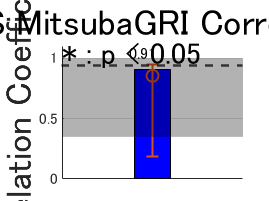

%-------------------------------------
% Exp1
%-------------------------------------
% データの準備
dataA = Exp1ThHMP15;
dataB = Exp1MiHMP15; 

numBootstrap = 10000; 

[corrA,corrAB,correlationDiffs] = Corr_Significance(dataA,dataB,numBootstrap);

% 95%信頼区間の下限を確認
sortedDiffs = sort(correlationDiffs);
threshold = sortedDiffs(round(numBootstrap*0.05)); 

% coef hisgram
x = Exp1ThH15;
y = Exp1MiH15;
amp = 1.0;

figure;
hold on;
Graph_Significance(x,y,corrA,corrAB,threshold,amp);
set(gca, 'XTick', []);
%xlabel('VR VS 2D','FontSize',18*amp);
title(sprintf('ThreeJSGRI VS MitsubaGRI Correlation Coefficient'),'FontSize',18*amp);
grid on;
hold off;

plotname = strcat(ana_result, '/ThreeJSGRIvsMitsubaGRI_Coefbar.jpg');
saveas(gcf, plotname);

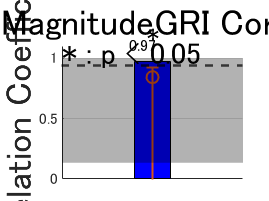

%-------------------------------------
% Exp2
%-------------------------------------
% データの準備
dataA = Exp1MiHMP15;
dataB = reshape(Exp2MiHMPT15,size(Exp2MiHMPT15,1),size(Exp2MiHMPT15,2),[]); 

numBootstrap = 10000; 

[corrA,corrAB,correlationDiffs] = Corr_Significance(dataA,dataB,numBootstrap);

% 95%信頼区間の下限を確認
sortedDiffs = sort(correlationDiffs);
threshold = sortedDiffs(round(numBootstrap*0.05)); 

% coef hisgram
x = Exp1MiH15;
y = Exp2MiH15;
amp = 1.0;

figure;
hold on;
Graph_Significance(x,y,corrA,corrAB,threshold,amp);
set(gca, 'XTick', []);
%xlabel('VR VS 2D','FontSize',18*amp);
title(sprintf('ThurstonGRI VS MagnitudeGRI Correlation Coefficient'),'FontSize',18*amp);
grid on;
hold off;

plotname = strcat(ana_result, '/ThurstonGRIvsMagnitudeGRI_Coefbar.jpg');
saveas(gcf, plotname);

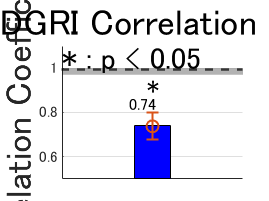

%-------------------------------------
% VRGRI Vs 2DGRI
%-------------------------------------
% データの準備
dataA = reshape(Exp3HMSPT,size(Exp3HMSPT,1),size(Exp3HMSPT,2),size(Exp3HMSPT,3),[]);
dataB = reshape(InoueHMSPT,size(InoueHMSPT,1),size(InoueHMSPT,2),size(InoueHMSPT,3),[]); 

numBootstrap = 10000; 

[corrA,corrAB,correlationDiffs] = Corr_Significance(dataA,dataB,numBootstrap);

% 95%信頼区間の下限を確認
sortedDiffs = sort(correlationDiffs);
threshold = sortedDiffs(round(numBootstrap*0.05)); 


% coef hisgram
x = Exp3H;
y = InoueH;
amp = 1.0;
figure;
hold on;

Graph_Significance(x,y,corrA,corrAB,threshold,amp);

set(gca, 'XTick', []);
%xlabel('VR VS 2D','FontSize',18*amp);
title(sprintf('VRGRI VS 2DGRI Correlation Coefficient'),'FontSize',18*amp);
grid on;
hold off;
plotname = strcat(ana_result, '/VRGRIvs2DGRI_Coefbar.jpg');
saveas(gcf, plotname);

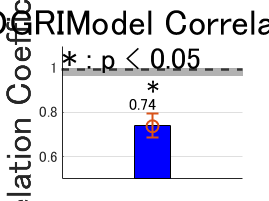

%-------------------------------------
% VRGRI Vs 2DGRIModel
%-------------------------------------
% データの準備
dataA = reshape(Exp3HMSPT,size(Exp3HMSPT,1),size(Exp3HMSPT,2),size(Exp3HMSPT,3),[]);
dataB = LumModelZsH; 

numBootstrap = 10000; 

[corrA,corrAB,correlationDiffs] = Corr_Significance(dataA,dataB,numBootstrap);

% 95%信頼区間の下限を確認
sortedDiffs = sort(correlationDiffs);
threshold = sortedDiffs(round(numBootstrap*0.05)); 


% coef hisgram
x = Exp3H;
y = LumModelZsH;
amp = 1.0;
figure;
hold on;

Graph_Significance(x,y,corrA,corrAB,threshold,amp);

set(gca, 'XTick', []);
%xlabel('VR VS 2D','FontSize',18*amp);
title(sprintf('VRGRI VS 2DGRIModel Correlation Coefficient'),'FontSize',18*amp);
grid on;
hold off;
plotname = strcat(ana_result, '/VRGRIvs2DGRIModel_Coefbar.jpg');
saveas(gcf, plotname);

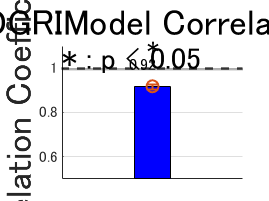

データAと2D演光沢感性指標の間に有意差があります（p < 0.05）


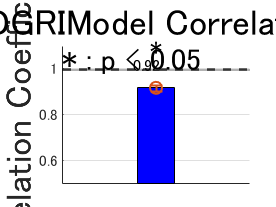

データAと2D演光沢感性指標の間に有意差があります（p < 0.05）


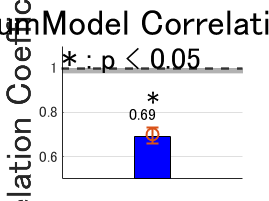

データAとデータBの間に有意差があります（p < 0.05）


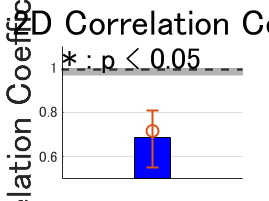

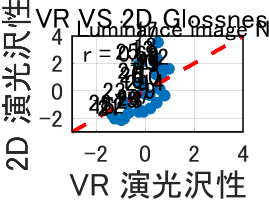

%-------------------------------------
% 2DGRI Vs 2DGRIModel
%-------------------------------------
% データの準備
dataA = reshape(InoueHMSPT,size(InoueHMSPT,1),size(InoueHMSPT,2),size(InoueHMSPT,3),[]);
dataB = LumModelZsH; 

numBootstrap = 10000; 

[corrA,corrAB,correlationDiffs] = Corr_Significance(dataA,dataB,numBootstrap);

% 95%信頼区間の下限を確認
sortedDiffs = sort(correlationDiffs);
threshold = sortedDiffs(round(numBootstrap*0.05)); 


% coef hisgram
x = InoueH;
y = LumModelZsH;
amp = 1.0;
figure;
hold on;

Graph_Significance(x,y,corrA,corrAB,threshold,amp);

set(gca, 'XTick', []);
%xlabel('VR VS 2D','FontSize',18*amp);
title(sprintf('2DGRI VS 2DGRIModel Correlation Coefficient'),'FontSize',18*amp);
grid on;
hold off;
plotname = strcat(ana_result, '/2DGRIvs2DGRIModel_Coefbar.jpg');
saveas(gcf, plotname);

%-------------------------------------
% VRGRI vs 2DGRI HDR_Material,Shape
%-------------------------------------
% データの準備
dataA = reshape(Exp3HMSPT,size(Exp3HMSPT,1),size(Exp3HMSPT,2),size(Exp3HMSPT,3),[]);
dataB = reshape(InoueHMSPT,size(InoueHMSPT,1),size(InoueHMSPT,2),size(InoueHMSPT,3),[]); 

numBootstrap = 10000; 
[numIllumination,MatNum,ShapeNum,~] = size(dataA); % 照明環境の数

% 結果保存用
correlationDiffs = zeros(numBootstrap, MatNum,ShapeNum);
corrA = zeros(numBootstrap,MatNum,ShapeNum);
corrAB = zeros(numBootstrap,MatNum,ShapeNum);
threshold = zeros(MatNum,ShapeNum);

for mat = 1:MatNum
    for shape = 1:ShapeNum        
        for i = 1:numBootstrap
            % === 1. データAでの基準相関係数を計算 ===
            % 1.a.b 条件ごとにブートストラップで平均を計算
            sampleA1 = mean(dataA(:,:,:, randi(size(dataA, 4), [1, size(dataA, 4)])), 4);
            sampleA2 = mean(dataA(:,:,:, randi(size(dataA, 4), [1, size(dataA, 4)])), 4);
            % 1.c 平均値データ間の相関係数
            corrA(i,mat,shape) = corr(sampleA1(:,mat,shape),sampleA2(:,mat,shape));

            % === 2. データAとデータBの相関係数を計算 ===
            sampleB = mean(dataB(:,:,:, randi(size(dataB, 4), [1, size(dataB, 4)])), 4);
            % 2.b データAとデータB間の相関係数
            corrAB(i,mat,shape) = corr(sampleA1(:,mat,shape),sampleB(:,mat,shape));

            % === 3. 相関係数の差を計算 ===
            correlationDiffs(i,mat,shape) = corrA(i,mat,shape) - corrAB(i,mat,shape);
        end
        
        % === 4. 有意差の判定 ===
        % 相関係数の差を昇順に並べる
        sortedDiffs = sort(correlationDiffs(:,mat,shape));
        % 95%信頼区間の下限を確認
        threshold(mat,shape) = sortedDiffs(round(numBootstrap*0.05)); 
        if threshold(mat,shape) > 0
            disp('AとBに有意差があります（p < 0.05）');
        else
            disp('AとBに有意差はありません（p >= 0.05）');
        end
    end
end

AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）
AとBに有意差があります（p < 0.05）


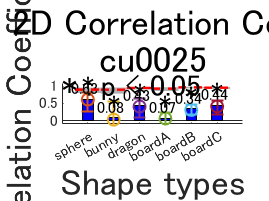

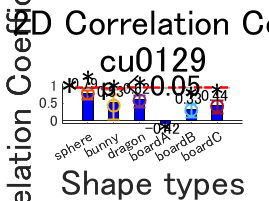

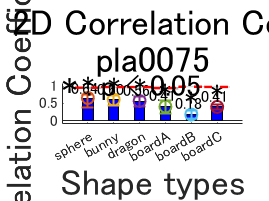

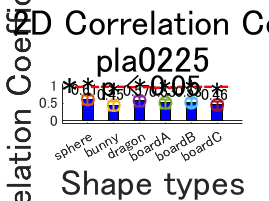

%-------------------------------------
% VRGRI vs 2DGRI HDR_Material,Shape graph
%-------------------------------------
amp = 1.0;

for mat = 1:MatNum
    figure;
    hold on;
    for shape = 1:ShapeNum   
        % coef and slope
        x = Exp3HMS(:,mat,shape);
        y = InoueHMS(:,mat,shape);
        r_value = corr(x,y);
        p = polyfit(x,y,1);

        maxValue = max(corrAB(:,mat,shape));
        minValue = min(corrAB(:,mat,shape));
        centerValue = mean(corrAB(:,mat,shape));
        upperError = maxValue - centerValue;
        lowerError = centerValue - minValue;
        
        % coef hisgram
        x_axis = shape;
        bar_width = 0.4;
        bar_coef = bar(x_axis,r_value,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');
        
        errorbar(x_axis, centerValue, lowerError, upperError, 'o', 'LineWidth', 1.0);
        
        graphtext1 = sprintf('%.2f',r_value);
        text(x_axis-0.1,(abs(r_value)+0.06)*r_value/abs(r_value),graphtext1,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',8*amp);
        if threshold(mat,shape) > 0
            graphtext3 = sprintf('*');
            text(x_axis,(abs(r_value)+0.12)*r_value/abs(r_value),graphtext3,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
        end

        ylim([-0.1,1.1]);
        y_Limits = ylim;
        x_Limits = xlim;
        SortCorrA = sort(corrA(:,mat,shape));
        maxorigin = SortCorrA(round(numBootstrap*0.95)); 
        minorigin = SortCorrA(round(numBootstrap*0.05)); 
        VR_95CI = fill([x_axis-0.5,x_axis+0.5,x_axis+0.5,x_axis-0.5], ...
            [minorigin,minorigin,maxorigin,maxorigin], ...
            'k', 'FaceAlpha', 0.3, 'EdgeColor', 'none');
        
        aveorigin = mean(corrA(:,mat,shape));
        VR_bar = plot([x_axis-0.5, x_axis+0.5], [aveorigin, aveorigin], 'r--', 'LineWidth', 1.2,'DisplayName', 'Within-subject average');
    end
    set(gca, 'XTick', 1:length(ShapeNames));
    xticklabels(ShapeNames);
    xlabel('Shape types','FontSize',18*amp);
    ylabel('Correlation Coefficient','FontSize',18*amp);
    title(sprintf('VR VS 2D Correlation Coefficient\n%s',string(MatNames1(mat))),'FontSize',18*amp);
    text(x_Limits(1)*0.9,y_Limits(2)*0.95, '* : p < 0.05', 'FontSize', 15*amp);
    %legend([bar_coef, VR_bar,VR_95CI], {'Row data', 'VR bar','VR 95 CI'}, 'Location', 'best','Orientation','vertical');
    hold off;
    plotname = sprintf('%s/VRvs2D_Coefbar_%s.jpg',ana_result, string(MatNames1(mat)));
    saveas(gcf, plotname);
end

%{
%-------------------------------------
% 2D GRI Vs 2DGRIModel
%-------------------------------------
% データの準備
dataA = reshape(InoueHMSPT,size(InoueHMSPT,1),size(InoueHMSPT,2),size(InoueHMSPT,3),[]);
dataB = LumModelZsH;

numBootstrap = 10000; 

% 結果保存用
correlationDiffs = zeros(numBootstrap, 1);
corrA = zeros(numBootstrap,1);
corrAB = zeros(numBootstrap,1);

for i = 1:numBootstrap
    % === 1. データAでの基準相関係数を計算 ===
    % 1.a.b 条件ごとにブートストラップで平均を計算
    sampleA1 = mean(mean(mean(dataA(:,:,:, randi(size(dataA, 4), [1, size(dataA, 4)])), 4),3),2);
    sampleA2 = mean(mean(mean(dataA(:,:,:, randi(size(dataA, 4), [1, size(dataA, 4)])), 4),3),2);

    % 1.c 平均値データ間の相関係数
    corrA(i) = corr(sampleA1(:),sampleA2(:));

    % === 2. データAとデータBの相関係数を計算 ===
    sampleB = dataB;
    % 2.b データAとデータB間の相関係数
    corrAB(i) = corr(sampleA1(:),sampleB(:));

    % === 3. 相関係数の差を計算 ===
    correlationDiffs(i) = corrA(i) - corrAB(i);
end

% === 4. 有意差の判定 ===
% 相関係数の差を昇順に並べる
sortedDiffs = sort(correlationDiffs);

% 95%信頼区間の下限を確認
threshold = sortedDiffs(round(numBootstrap*0.05)); 
if threshold > 0
    disp('データAと2D演光沢感性指標の間に有意差があります（p < 0.05）');
else
    disp('データAと2D演光沢感性指標の間に有意差はありません（p >= 0.05）');
end

%-------------------------------------
% 2D GRI Vs 2DGRIModel HDR graph
%-------------------------------------
amp = 1.0;

% coef and slope
x = InoueH;
y = LumModelZsH;
r = corr(x,y);
r_value = r;
p = polyfit(x,y,1);

% coef hisgram
figure;
hold on;
x_axis = 1;
bar_width = 0.4;
bar_coef = bar(x_axis,r_value,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');

maxValue = max(corrAB);
minValue = min(corrAB);
centerValue = mean(corrAB);
upperError = maxValue - centerValue;
lowerError = centerValue - minValue;
errorbar(x_axis, centerValue, lowerError, upperError, 'o', 'LineWidth', 1.0);

graphtext1 = sprintf('%.2f',r_value);
text(1*0.9,(abs(r_value)+0.06)*r_value/abs(r_value),graphtext1,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',8*amp);
if threshold > 0
    graphtext3 = sprintf('*');
    text(1,(abs(r_value)+0.12)*r_value/abs(r_value),graphtext3,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
end

ylim([0.5,1.1]);
y_Limits = ylim;
x_Limits = xlim;
maxorigin = max(corrA);
minorigin = min(corrA);
VR_95CI = fill([x_Limits(1),x_Limits(2),x_Limits(2),x_Limits(1)], ...
    [minorigin,minorigin,maxorigin,maxorigin], ...
    'k', 'FaceAlpha', 0.3, 'EdgeColor', 'none');

aveorigin = mean(corrA);
VR_bar = yline(aveorigin, 'k--', 'LineWidth', 1.2, 'DisplayName', 'Within-subject average');

set(gca, 'XTick', []);
%xlabel('VR VS 2D','FontSize',18*amp);
ylabel('Correlation Coefficient','FontSize',18*amp);
title(sprintf('2DGRI VS 2DGRIModel Correlation Coefficient'),'FontSize',18*amp);
text(x_Limits(1)*0.9,y_Limits(2)*0.95, '* : p < 0.05', 'FontSize', 15*amp);
%legend([bar_coef, VR_bar,VR_95CI], {'Row data', 'VR bar','VR 95 CI'}, 'Location', 'best','Orientation','vertical');
grid on;
hold off;
plotname = strcat(ana_result, '/2DvsLumModel_HDR_Coefbar.jpg');
saveas(gcf, plotname);

%-------------------------------------
% VRGRI Vs 2DGRIModel
%-------------------------------------
% データの準備
dataA = reshape(Exp3HMSPT,size(Exp3HMSPT,1),size(Exp3HMSPT,2),size(Exp3HMSPT,3),[]);
dataB = reshape(InoueHMSPT,size(InoueHMSPT,1),size(InoueHMSPT,2),size(InoueHMSPT,3),[]); 

numBootstrap = 10000; 

% 結果保存用
correlationDiffs = zeros(numBootstrap, 1);
corrA = zeros(numBootstrap,1);
corrAB = zeros(numBootstrap,1);

for i = 1:numBootstrap
    % === 1. データAでの基準相関係数を計算 ===
    % 1.a.b 条件ごとにブートストラップで平均を計算
    sampleA1 = mean(mean(mean(dataA(:,:,:, randi(size(dataA, 4), [1, size(dataA, 4)])), 4),3),2);
    sampleA2 = mean(mean(mean(dataA(:,:,:, randi(size(dataA, 4), [1, size(dataA, 4)])), 4),3),2);

    % 1.c 平均値データ間の相関係数
    corrA(i) = corr(sampleA1(:),sampleA2(:));

    % === 2. データAとデータBの相関係数を計算 ===
    sampleB = dataB;
    % 2.b データAとデータB間の相関係数
    corrAB(i) = corr(sampleA1(:),sampleB(:));

    % === 3. 相関係数の差を計算 ===
    correlationDiffs(i) = corrA(i) - corrAB(i);
end

% === 4. 有意差の判定 ===
% 相関係数の差を昇順に並べる
sortedDiffs = sort(correlationDiffs);

% 95%信頼区間の下限を確認
threshold = sortedDiffs(round(numBootstrap*0.05)); 
if threshold > 0
    disp('データAと2D演光沢感性指標の間に有意差があります（p < 0.05）');
else
    disp('データAと2D演光沢感性指標の間に有意差はありません（p >= 0.05）');
end

%-------------------------------------
% VRGRI Vs 2DGRIModel HDR graph
%-------------------------------------
amp = 1.0;

% coef and slope
x = Exp3H;
y = LumModelH;
r = corr(x,y);
r_value = r;
p = polyfit(x,y,1);

% coef hisgram
figure;
hold on;
x_axis = 1;
bar_width = 0.4;
bar_coef = bar(x_axis,r_value,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');

maxValue = max(corrAB);
minValue = min(corrAB);
centerValue = mean(corrAB);
upperError = maxValue - centerValue;
lowerError = centerValue - minValue;
errorbar(x_axis, centerValue, lowerError, upperError, 'o', 'LineWidth', 1.0);

graphtext1 = sprintf('%.2f',r_value);
text(1*0.9,(abs(r_value)+0.06)*r_value/abs(r_value),graphtext1,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',8*amp);
if threshold > 0
    graphtext3 = sprintf('*');
    text(1,(abs(r_value)+0.12)*r_value/abs(r_value),graphtext3,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
end

ylim([0.5,1.1]);
y_Limits = ylim;
x_Limits = xlim;
maxorigin = max(corrA);
minorigin = min(corrA);
VR_95CI = fill([x_Limits(1),x_Limits(2),x_Limits(2),x_Limits(1)], ...
    [minorigin,minorigin,maxorigin,maxorigin], ...
    'k', 'FaceAlpha', 0.3, 'EdgeColor', 'none');

aveorigin = mean(corrA);
VR_bar = yline(aveorigin, 'k--', 'LineWidth', 1.2, 'DisplayName', 'Within-subject average');

set(gca, 'XTick', []);
%xlabel('VR VS 2D','FontSize',18*amp);
ylabel('Correlation Coefficient','FontSize',18*amp);
title(sprintf('VR VS 2DLumModel Correlation Coefficient'),'FontSize',18*amp);
text(x_Limits(1)*0.9,y_Limits(2)*0.95, '* : p < 0.05', 'FontSize', 15*amp);
%legend([bar_coef, VR_bar,VR_95CI], {'Row data', 'VR bar','VR 95 CI'}, 'Location', 'best','Orientation','vertical');
grid on;
hold off;
plotname = strcat(ana_result, '/VRvsLumModel_HDR_Coefbar.jpg');
saveas(gcf, plotname);
%}

%{
%-------------------------------------
% VRGRI vs 2DGRI HDR
%-------------------------------------
% データの準備
dataA = reshape(Exp3HMSPT,size(Exp3HMSPT,1),size(Exp3HMSPT,2),size(Exp3HMSPT,3),[]);
dataB = reshape(InoueHMSPT,size(InoueHMSPT,1),size(InoueHMSPT,2),size(InoueHMSPT,3),[]); 

numBootstrap = 10000; 
[numIllumination,MatNum,ShapeNum,~] = size(dataA); % 照明環境の数

% 結果保存用
correlationDiffs = zeros(numBootstrap, 1);
corrA = zeros(numBootstrap,1);
corrAB = zeros(numBootstrap,1);

for i = 1:numBootstrap
    % === 1. データAでの基準相関係数を計算 ===
    % 1.a.b 条件ごとにブートストラップで平均を計算
    sampleA1 = mean(mean(mean(dataA(:,:,:, randi(size(dataA, 4), [1, size(dataA, 4)])), 4),3),2);
    sampleA2 = mean(mean(mean(dataA(:,:,:, randi(size(dataA, 4), [1, size(dataA, 4)])), 4),3),2);

    % 1.c 平均値データ間の相関係数
    corrA(i) = corr(sampleA1(:),sampleA2(:));

    % === 2. データAとデータBの相関係数を計算 ===
    sampleB = mean(mean(mean(dataB(:, randi(size(dataB, 4), [1, size(dataB, 4)])), 4),3),2);
    % 2.b データAとデータB間の相関係数
    corrAB(i) = corr(sampleA1(:),sampleB(:));

    % === 3. 相関係数の差を計算 ===
    correlationDiffs(i) = corrA(i) - corrAB(i);
end

% === 4. 有意差の判定 ===
% 相関係数の差を昇順に並べる
sortedDiffs = sort(correlationDiffs);

% 95%信頼区間の下限を確認
threshold = sortedDiffs(round(numBootstrap*0.05)); 
if threshold > 0
    disp('データAとデータBの間に有意差があります（p < 0.05）');
else
    disp('データAとデータBの間に有意差はありません（p >= 0.05）');
end
%-------------------------------------
% VRGRI vs 2DGRI HDR graph
%-------------------------------------
amp = 1.0;

% coef and slope
x = Exp3H;
y = InoueH;
r = corr(x,y);
r_value = r;
p = polyfit(x,y,1);

% coef hisgram
figure;
hold on;
x_axis = 1;
bar_width = 0.4;
bar_coef = bar(x_axis,r_value,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');

maxValue = max(corrAB);
minValue = min(corrAB);
centerValue = mean(corrAB);
upperError = maxValue - centerValue;
lowerError = centerValue - minValue;
errorbar(x_axis, centerValue, lowerError, upperError, 'o', 'LineWidth', 1.0);

graphtext1 = sprintf('%.2f',r_value);
text(1*0.9,(abs(r_value)+0.06)*r_value/abs(r_value),graphtext1,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',8*amp);
if threshold > 0
    graphtext3 = sprintf('*');
    text(1,(abs(r_value)+0.12)*r_value/abs(r_value),graphtext3,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
end

ylim([0.5,1.1]);
y_Limits = ylim;
x_Limits = xlim;
maxorigin = max(corrA);
minorigin = min(corrA);
VR_95CI = fill([x_Limits(1),x_Limits(2),x_Limits(2),x_Limits(1)], ...
    [minorigin,minorigin,maxorigin,maxorigin], ...
    'k', 'FaceAlpha', 0.3, 'EdgeColor', 'none');

aveorigin = mean(corrA);
VR_bar = yline(aveorigin, 'k--', 'LineWidth', 1.2, 'DisplayName', 'Within-subject average');

set(gca, 'XTick', []);
%xlabel('VR VS 2D','FontSize',18*amp);
ylabel('Correlation Coefficient','FontSize',18*amp);
title(sprintf('VR VS 2D Correlation Coefficient'),'FontSize',18*amp);
text(x_Limits(1)*0.9,y_Limits(2)*0.95, '* : p < 0.05', 'FontSize', 15*amp);
%legend([bar_coef, VR_bar,VR_95CI], {'Row data', 'VR bar','VR 95 CI'}, 'Location', 'best','Orientation','vertical');
grid on;
hold off;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Coefbarv2.jpg');
saveas(gcf, plotname);
%}

%trash
%{
%-------------------------------------
% HDR 
%-------------------------------------
% データの準備
dataA = reshape(Exp3HMSPT,size(Exp3HMSPT,1),[]);
dataB = reshape(InoueHMS,size(InoueHMS,1),[]);  

numBootstrap = 1000; 
numIllumination = size(dataA, 1); % 照明環境の数
sampleSizeA = size(dataA, 2); 
sampleSizeB = size(dataB, 2); 

% 結果保存用
corrA = zeros(numBootstrap,1);
corrAB = zeros(numBootstrap,1);
correlationDiffs = zeros(numBootstrap, 1);

for i = 1:numBootstrap
    % === 1. データAでの基準相関係数を計算 ===
    % 1.a 照明環境ごとにブートストラップで平均を計算
    meanA1 = zeros(numIllumination, 1);
    meanA2 = zeros(numIllumination, 1);
    for j = 1:numIllumination
        % ランダムサンプリング
        resampleIdx1 = randi(sampleSizeA, sampleSizeA, 1);
        resampleIdx2 = randi(sampleSizeA, sampleSizeA, 1);
        meanA1(j) = mean(dataA(j, resampleIdx1));
        meanA2(j) = mean(dataA(j, resampleIdx2));
    end
    % 1.c 平均値データ間の相関係数
    corrA(i) = corr(meanA1, meanA2);

    % === 2. データBでの相関係数を計算 ===
    meanB = zeros(numIllumination, 1);
    for j = 1:numIllumination
        % ランダムサンプリング
        resampleIdx = randi(sampleSizeB, sampleSizeB, 1);
        meanB(j) = mean(dataB(j, resampleIdx));
    end
    % 2.b データAとデータB間の相関係数
    corrAB(i) = corr(meanA1, meanB);

    % === 3. 相関係数の差を計算 ===
    correlationDiffs(i) = corrA(i) - corrAB(i);
end

% === 4. 有意差の判定 ===
% 相関係数の差を昇順に並べる
sortedDiffs = sort(correlationDiffs);

% 95%信頼区間の下限を確認
threshold = sortedDiffs(round(numBootstrap*0.05)); 
if threshold > 0
    disp('データAとデータBの間に有意差があります（p < 0.05）');
else
    disp('データAとデータBの間に有意差はありません（p >= 0.05）');
end
%-------------------------------------
% HDR graph
%-------------------------------------
amp = 1.0;

% coef and slope
x = Exp3H;
y = InoueH;
r = corrcoef(x,y);
r_value = r(1,2);
p = polyfit(x,y,1);

% coef hisgram
figure;
hold on;
x = 1;
bar_width = 0.4;
bar_coef = bar(x,r_value,bar_width, 'FaceColor', 'b', 'DisplayName', 'Coef');

maxValue = max(corrAB);
minValue = min(corrAB);
centerValue = (maxValue + minValue) / 2;
upperError = maxValue - centerValue;
lowerError = centerValue - minValue;
errorbar(x, centerValue, lowerError, upperError, 'o', 'LineWidth', 1.0);

graphtext1 = sprintf('%.2f',r_value);
text(1,(abs(r_value)+0.06)*r_value/abs(r_value),graphtext1,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',8*amp);
if threshold > 0
    graphtext3 = sprintf('*');
    text(1,(abs(r_value)+0.12)*r_value/abs(r_value),graphtext3,'HorizontalAlignment','center','VerticalAlignment','bottom','FontSize',12*amp);
end

ylim([0,1.3]);
y_Limits = ylim;
x_Limits = xlim;
maxorigin = max(corrA);
minorigin = min(corrA);
fill([x_Limits(1),x_Limits(2)], [maxorigin, minorigin], 'cyan', 'FaceAlpha', 0.5, 'EdgeColor', 'none');

aveorigin = mean(corrA);
yline(aveorigin, 'k--', 'LineWidth', 1.2, 'DisplayName', 'エラー平均');

xlabel('Light image','FontSize',18*amp);
ylabel('Correlation Coefficient','FontSize',18*amp);
title(sprintf('VR VS 2D Correlation Coefficient'),'FontSize',18*amp);
text(x_Limits(1)*0.9,y_Limits(2)*0.9, '* : p-value < 0.05', 'FontSize', 15*amp);
grid on;
hold off;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Coefbarv2.jpg');
saveas(gcf, plotname);


%散布図
figure;
x = Exp3H(:);
y = InoueH(:);
r = corrcoef(x,y);
r_value = r(1,2);
p = polyfit(x,y,1);
p_fit = polyval(p,x);

scatter(x,y,'filled');
hold on;
%plot(x,p_fit,'r-','LineWidth',1.5);

x_limits = xlim;
y_limits = ylim;
xlim([min(x_limits(1),y_limits(1)) max(x_limits(2),y_limits(2))]);
ylim([min(x_limits(1),y_limits(1)) max(x_limits(2),y_limits(2))]);
x_limits = xlim;
y_limits = ylim;
common_limits = [min([x_limits, y_limits]), max([x_limits, y_limits])];
plot(common_limits, common_limits, 'r--', 'LineWidth', 2);
% グラフ囲む
rectangle('Position', [x_limits(1), y_limits(1), diff(x_limits), diff(y_limits)], ...
          'EdgeColor', 'k', 'LineWidth', 0.75);
% HDR No
for point = 1:length(x)
    text(x(point)-0.01, y(point)+0.01, num2str(HDRNames3(point)), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right','FontSize',12*amp);
end
hold off;

text(x_limits(1)*0.95,y_limits(2)*0.9, ...
    sprintf('Luminance image No.\n r = 0.69'), 'FontSize', 12*amp);
set(gca,'FontSize',12*amp);
xlabel('VR 演光沢性','FontSize',16*amp);
ylabel('2D 演光沢性','FontSize',16*amp);
%title(sprintf('VR VS 2D Glossness\n correlation coefficient : %.2f,Slope : %.2f', r_value,p(1)));
title(sprintf('VR VS 2D Glossness'),'FontSize',14*amp);
grid on;
plotname = strcat(ana_result, '/Exp3vsOld_HDR_Coef.jpg');
saveas(gcf, plotname);
%}